# Funciones anónimas

## Aplicación de las funciones anónimas

### Ejercicio 1 (análisis numérico)

Suponga el lector que está diseñando un tanque esférico para almacenar agua para un poblado pequeño en un país en desarrollo. El volumen de líquido que puede contener se calcula con


$$V=\pi h^2 \frac{\left\lbrack 3R-h\right\rbrack }{3}$$


donde $V$ es el volumen en ${\mathrm{m}}^3$, $h$ es la profundidad del agua en el tanque en $\mathrm{m}$ y $R$ es el radio del tanque en $\mathrm{m}$.

**Figura 1.** Tanque esférico.

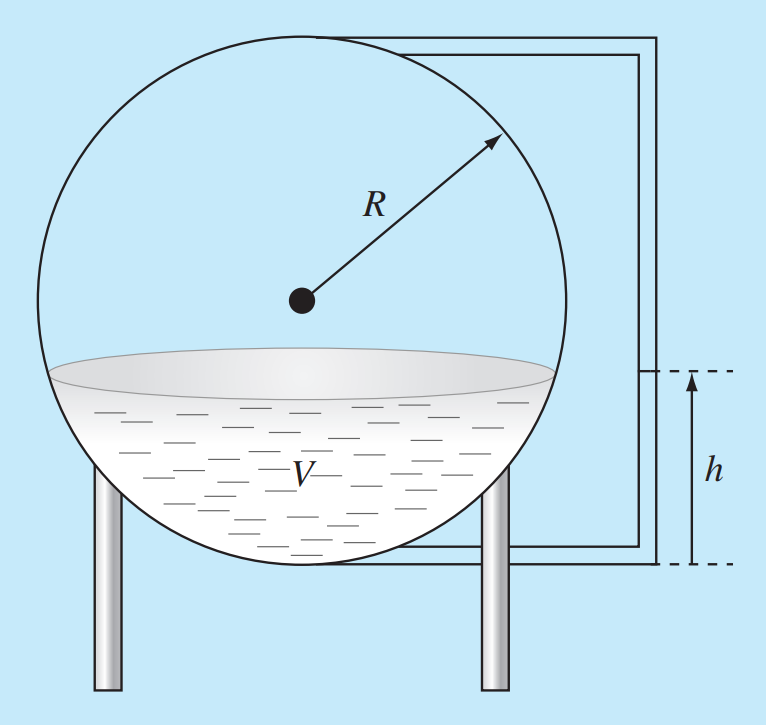

*Tomado de Métodos numéricos para ingenieros de Steven C. Chapra & Raymond P. Canale.*

Si $R=3\;\mathrm{m}$, ¿a qué profundidad debe llenarse el tanque de modo que contenga $30\;{\mathrm{m}}^3$?


$$30=\pi \;h^{2\;} \frac{\left\lbrack 9-h\right\rbrack \;}{3}=f\;\to f\left(h\right)=\pi \;h^{2\;} \frac{\left\lbrack 9-h\right\rbrack \;}{3}-30\;$$
 

**Recomendación 1:** Primero establecer manualmente la función de la cual se requiere determinar la raíz.

**Recomendación 2:** Utilizar la función `fzero` (consultar en la documentación si es necesario).

*Ejercicio modificado de Chapra & Canale, 2007.*

### Solución

f=@(h) pi*h^2 .* ((9-h)/3)-30;
f(2.03)  %punto de partida

ans = 0.0783

r0=2.03;
raiz=fzero(f,r0)

raiz = 2.0269

### Ejercicio 2 (análisis numérico)

En una sección de tubo, la caída de presión se calcula así:


$$\Delta \rho =f\frac{L\rho V^2 }{2D}$$


donde $\Delta \rho$ es la caída de presión en $\textrm{Pa}$, $f$ es el factor de fricción, $L$ es la longitud del tubo en $\mathrm{m}$, $\rho$ es la densidad en $\textrm{kg}/{\mathrm{m}}^3$, $V$ es la velocidad en $\mathrm{m}/\mathrm{s}$, y $D$ es el diámetro en $\mathrm{m}$. Para el flujo turbulento, la *ecuación de Colebrook* proporciona un medio para calcular el factor de fricción, 


$$\frac{1}{\sqrt{f}}=-2\log \left(\frac{\varepsilon }{3\ldotp 7D}+\frac{2\ldotp 51}{\textrm{Re}\sqrt{f}}\right)$$


donde $\varepsilon$ es la rugosidad en $\mathrm{m}$ y $\textrm{Re}$ es el *número de Reynolds* que se define como


$$\textrm{Re}=\frac{\rho \textrm{VD}}{\mu }$$


donde $\mu$ es la viscosidad dinámica en $\mathrm{N}\cdot \mathrm{s}/{\mathrm{m}}^2$.

Determinar $\Delta \rho$ para un tramo horizontal de tubo liso de $0\ldotp 2\;\mathrm{m}$ de longitud, dadas $\rho =1\ldotp 23\;\textrm{kg}/{\mathrm{m}}^3$, $\mu =1\ldotp 79\times {10}^{-5} \;\mathrm{N}\cdot \mathrm{m}/{\mathrm{s}}^2$, $D=0\ldotp 005\;\mathrm{m}$, $V=40\;\mathrm{m}/\mathrm{s}$ y $\varepsilon =0\ldotp 0015\;\textrm{mm}$. Determinar también el factor de fricción $f$.

**Nota:** Obsérvese que los tubos lisos tienen $\textrm{Re}<{10}^5$, un valor inicial apropiado se obtiene con el uso de la *fórmula de Blasius*, $f=\frac{0\ldotp 316}{{\textrm{Re}}^{0\ldotp 25} }$.

**Recomendación 1:** Primero determinar el número de Reynolds para verificar si se puede o no utilizar la fórmula de Blasius. Luego, determinar manualmente la función de la cual se requiere determinar la raíz (reemplazar datos en la ecuación de Colebrook) para finalmente obtener $\Delta \rho$.

**Recomendación 2:** Utilizar la función `fzero` (consultar en la documentación si es necesario).

*Ejercicio modificado de Chapra & Canale, 2007.*

### Solución

L=0.2;         %m 
rho=1.23;      %kg/m^3 
mu=1.79e-5;    %N * m/s^2
D=0.005;       %m
V=40;          %m/s
E=0.0015;      %mm
%obtencion del numero de Reynolds 
Re=(rho*V*D)/mu;
if Re< 10e5 
    f=0.316/Re^0.25  %factor de friccion
end

f = 0.0292

Dp=(f*L*rho*V^2)/2*D

Dp = 0.0287

### Ejercicio 3 (análisis numérico)

En ingeniería estructural, la fórmula de la secante define la fuerza por unidad de área, $P/A$, que ocasiona la tensión máxima $\sigma_m$ en una columna que tiene una razón de esbeltez $L/k$ dada es:


$$\frac{P}{A}=\frac{\sigma_m }{1+\left(ec/k^2 \right)\sec \left\lbrack 0\ldotp 5\sqrt{P/\left(EA\right)}\left(L/k\right)\right\rbrack }$$


donde $\textrm{ec}/k^2$ es la razón de excentricidad, y $E$ es el módulo de elasticidad. Si para una viga de acero, $E=200000\;\textrm{MPa}$, $\textrm{ec}/k^2 =0\ldotp 4$ y $\sigma_m =250\;\textrm{MPa}$, calcule $P/A$ para $L/k=50$. Recuerde que $\sec \;x=1/\cos \;x$.


$$\frac{P}{A}=\frac{\sigma_m }{1+\left(ec/k^2 \right)\sec \left\lbrack 0\ldotp 5\sqrt{P/\left(EA\right)}\left(L/k\right)\right\rbrack }=g\;\;\to \;g\left(\frac{P}{A}\right)=\frac{\sigma_m }{1+\left(ec/k^2 \right)\sec \left\lbrack 0\ldotp 5\sqrt{P/\left(EA\right)}\left(L/k\right)\right\rbrack }-\frac{P}{A}$$


**Recomendación:** Utilizar la función `fzero` (consultar en la documentación si es necesario).

*Ejercicio tomado de Chapra & Canale, 2007.*

E=200000e6;  %Pa
eclk=0.4;
phi=250e6;   %Pa
Lk=50;  
%P/A=c 
%secante=sec(0.5* sqrt(c* (1/E)));
g=@(c) (phi/(1+eclk* (1/cos(0.5* sqrt(c* (1/E)))) *Lk)) - c ;
g(178)

ans = 1.1905e+07

g0=178;
raiz=fzero(g,g0)

raiz = 1.1905e+07

### Ejercicio 4 (análisis numérico)

En ingeniería oceanográfica, la ecuación de una ola estacionaria reflejada en un puerto está dada por $\lambda =16$, $t=12$, $v=48$:


$$h=h_0 \left\lbrack \mathrm{sen}\left(\frac{2\pi x}{\lambda }\right)\cos \left(\frac{2\pi tv}{\lambda }\right)+e^{-x} \right\rbrack$$


Resuelva para el valor positivo más bajo de $x$, si $h=0\ldotp 5h_0$.

**Recomendación:** Utilizar la función `fzero` (consultar en la documentación si es necesario).

*Ejercicio tomado de Chapra & Canale, 2007.*


$$0\ldotp 5h_0 =h_0 \left\lbrack \mathrm{sen}\left(\frac{2\pi x}{\lambda }\right)\cos \left(\frac{2\pi tv}{\lambda }\right)+e^{-x} \right\rbrack \;\to \;0\ldotp 5=\mathrm{sen}\left(\frac{2\pi x}{\lambda }\right)\cos \left(\frac{2\pi tv}{\lambda }\right)+e^{-x} \;=f\;\;\;\to f\left(x\right)=\mathrm{sen}\left(\frac{2\pi x}{\lambda }\right)\cos \left(\frac{2\pi tv}{\lambda }\right)+e^{-x} --0\ldotp 5$$


### Solución

lamda=16; 
t=12;
v=48;
f=@(x) sin(2*pi*x/lamda)*cos(2*pi*t*v/lamda) + exp(-x) -0.5 ; 
f(6.6)

ans = 0.0239

f0=6.6;  %valor de referencia 
r=fzero(f,f0)

r = 6.6704

### Ejercicio 5 (ecuaciones diferenciales ordinarias)

Un tanque esférico tiene un orificio circular en el fondo a través del cual fluye líquido.

**Figura 2.** Tanque esférico.

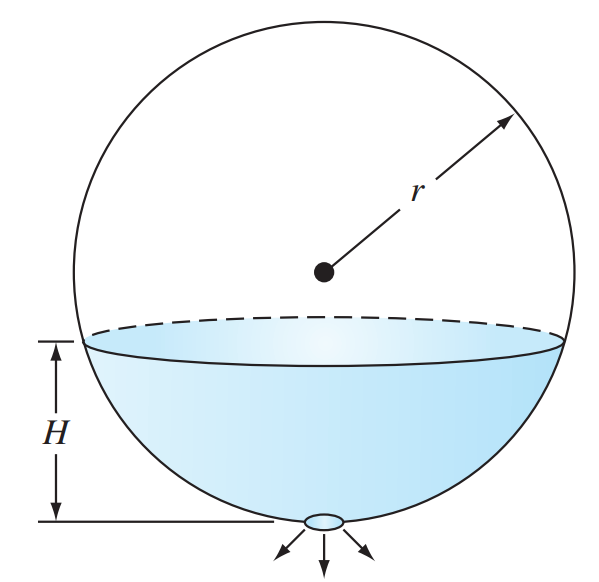

*Tomado de Métodos numéricos para ingenieros de Steven C. Chapra & Raymond P. Canale.*

La tasa de flujo a través del agujero se calcula como:


$$Q_{\textrm{sal}} =\textrm{CA}\sqrt{2\textrm{gH}}$$


donde $Q_{\textrm{sal}}$ es el flujo de salida en ${\mathrm{m}}^3 /\mathrm{s}$, $C$ es un coeficiente obtenido en forma empírica, $A$ es el área del orificio en ${\mathrm{m}}^2$, $g$ es la constante gravitacional ($9\ldotp 81\;\mathrm{m}/{\mathrm{s}}^2$) y $H$ es la profundidad del líquido dentro del tanque. Determinar cuánto tiempo tomaría que el agua fluyera por completo de un tanque de $3\;\mathrm{m}$ de diámetro con altura inicial de $2\ldotp 75\;\mathrm{m}$. Observe que el orificio tiene un diámetro de $3\;\textrm{cm}$ y $C=0\ldotp 55$.

**Recomendación:** Utilizar la función `ode45` (consultar en la documentación si es necesario).

*Ejercicio tomado de Chapra & Canale, 2007.*

### Solución

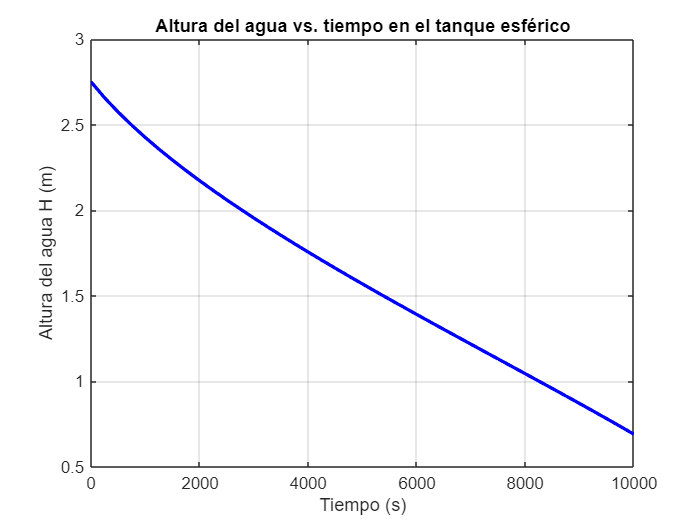

% Parámetros
R = 1.5;                 % Radio del tanque (m)
C = 0.55;                % Coeficiente de descarga
d = 0.03;                % Diámetro del orificio (m)
A = pi * (d/2)^2;        % Área del orificio (m^2)
g = 9.81;                % Gravedad (m/s^2)

% Ecuación diferencial usando funciones anónimas
dHdt = @(t, H) - (C * A * sqrt(2 * g * H)) ./ (pi * H .* (3 * R - (4/3) * H));

% Condición inicial
H0 = 2.75;

% Resolver usando ode45
[t, H] = ode45(dHdt, [0 10000], H0);  % Intervalo amplio para asegurar vaciado

% Graficar
plot(t, H, 'b', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Altura del agua H (m)');
title('Altura del agua vs. tiempo en el tanque esférico');
grid on;


% Tiempo total de vaciado
idx = find(H <= 0, 1);  % Encuentra cuando H se hace cero o menor
if ~isempty(idx)
    tiempo_vaciado = t(idx);
    fprintf('Tiempo total de vaciado: %.2f segundos\n', tiempo_vaciado);
else
    fprintf('El tanque no se vació completamente en el intervalo simulado.\n');
end

El tanque no se vació completamente en el intervalo simulado.


### Ejercicio 6 (ecuaciones diferenciales ordinarias)

Si se drena el agua desde un tanque cilíndrico vertical por medio de abrir una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio conforme se drene. Como se ve, la tasa a la que el nivel del agua disminuye es:


$$\frac{\textrm{dy}}{\textrm{dt}}=-k\sqrt{y}$$


donde $k$ es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y agujero de drenaje. La profundidad del agua $y$ se mide en metros y el tiempo $t$ en minutos. Si $k=0\ldotp 06$, determine cuánto tiempo se requiere para vaciar el tanque si el nivel del fluido se encuentra en un inicio a $3\;\mathrm{m}$.

**Recomendación:** Utilizar la función `ode45` (consultar en la documentación si es necesario).

*Ejercicio tomado de Chapra & Canale, 2007.*

### Solución

k=0.06;
y0=3;   %metros
Intervalo=[0 100];
dydt=@(t,y) -k*sqrt(y) ;
[abd, ord]=ode45(dydt,Intervalo,y0)

abd =          0
    1.4502
    2.9005
    4.3507
    5.8010
    8.3010
   10.8010
   13.3010
   15.8010
   18.3010


ord =    3.0000 + 0.0000i
   2.8512 + 0.0000i
   2.7061 + 0.0000i
   2.5649 + 0.0000i
   2.4274 + 0.0000i
   2.1994 + 0.0000i
   1.9825 + 0.0000i
   1.7769 + 0.0000i
   1.5826 + 0.0000i
   1.3995 + 0.0000i


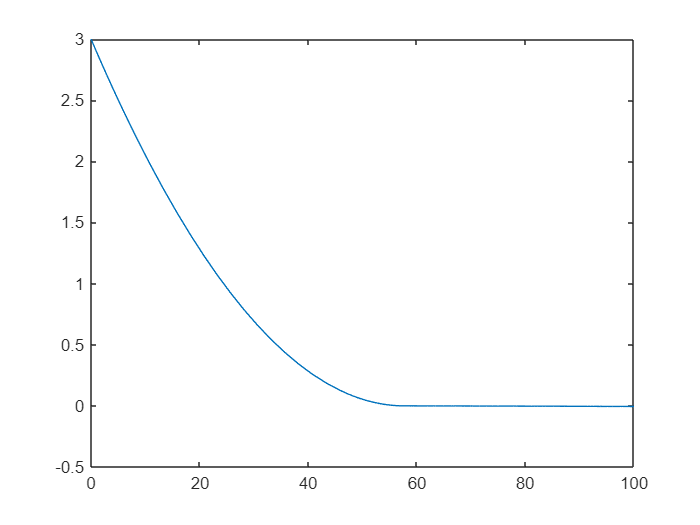

plot(abd, ord)